syms x y x_0 y_0 real

Building tyalor extantion part.

f = sin(x_0)*log(x_0*y_0)

$$f = \log\left(x_{0}\,y_{0}\right)\,\sin\left(x_{0}\right)$$

Tylor_1 =  1/factorial(1)*(diff(f,x_0,1)*(x-1)^1 + diff(f,y_0,1)*(y-1)^1) 

$$Tylor\_1 = \left(\frac{\sin\left(x_{0}\right)}{x_{0}}+\log\left(x_{0}\,y_{0}\right)\,\cos\left(x_{0}\right)\right)\,\left(x-1\right)+\frac{\sin\left(x_{0}\right)\,\left(y-1\right)}{y_{0}}$$

Tylor_2 =  1/factorial(2)*(diff(f,x_0,2)*(x-1)^2 + diff(f,y_0,2)*(y-1)^2 +  2*diff(diff(f,x_0,1),y_0,1)*(x-1)*(y-1)) 

$$Tylor\_2 = \frac{\cos\left(x_{0}\right)\,\left(x-1\right)\,\left(y-1\right)}{y_{0}}-\frac{\sin\left(x_{0}\right)\,{\left(y-1\right)}^{2}}{2\,{y_{0}}^{2}}-\frac{{\left(x-1\right)}^{2}\,\left(\log\left(x_{0}\,y_{0}\right)\,\sin\left(x_{0}\right)-\frac{2\,\cos\left(x_{0}\right)}{x_{0}}+\frac{\sin\left(x_{0}\right)}{{x_{0}}^{2}}\right)}{2}$$

Tylor_3 =  1/factorial(3)*(diff(f,x_0,3)*(x-1)^3 + diff(f,y_0,3)*(y-1)^3 + 3*diff(diff(f,x_0,2),y_0,1)*(x-1)^2*(y-1) + 3*diff(diff(f,x_0,1),y_0,2)*(x-1)*(y-1)^2) 

$$Tylor\_3 = \frac{\sin\left(x_{0}\right)\,{\left(y-1\right)}^{3}}{3\,{y_{0}}^{3}}-\frac{{\left(x-1\right)}^{3}\,\left(\frac{3\,\cos\left(x_{0}\right)}{{x_{0}}^{2}}+\frac{3\,\sin\left(x_{0}\right)}{x_{0}}-\frac{2\,\sin\left(x_{0}\right)}{{x_{0}}^{3}}+\log\left(x_{0}\,y_{0}\right)\,\cos\left(x_{0}\right)\right)}{6}-\frac{\cos\left(x_{0}\right)\,\left(x-1\right)\,{\left(y-1\right)}^{2}}{2\,{y_{0}}^{2}}-\frac{\sin\left(x_{0}\right)\,{\left(x-1\right)}^{2}\,\left(y-1\right)}{2\,y_{0}}$$

Symbolic Present tyalor extanation

Order 1:

Tylor_Order1 = simplify(f + Tylor_1)

$$Tylor\_Order1 = \log\left(x_{0}\,y_{0}\right)\,\sin\left(x_{0}\right)+\sin\left(1\right)\,\left(x-1\right)+\sin\left(1\right)\,\left(y-1\right)$$

Tylor_Order2 = simplify(f + Tylor_1 + Tylor_2)

$$Tylor\_Order2 = \log\left(x_{0}\,y_{0}\right)\,\sin\left(x_{0}\right)-\frac{\sin\left(1\right)\,{\left(y-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{2}\,\left(2\,\cos\left(1\right)-\sin\left(1\right)\right)}{2}+\sin\left(1\right)\,\left(x-1\right)+\sin\left(1\right)\,\left(y-1\right)+\cos\left(1\right)\,\left(x-1\right)\,\left(y-1\right)$$

Tylor_Order3 = simplify(f + Tylor_1 + Tylor_2 + Tylor_3)

$$Tylor\_Order3 = \log\left(x_{0}\,y_{0}\right)\,\sin\left(x_{0}\right)-\frac{\sin\left(1\right)\,{\left(y-1\right)}^{2}}{2}+\frac{\sin\left(1\right)\,{\left(y-1\right)}^{3}}{3}-\frac{\left(3\,\cos\left(1\right)+\sin\left(1\right)\right)\,{\left(x-1\right)}^{3}}{6}+\frac{{\left(x-1\right)}^{2}\,\left(2\,\cos\left(1\right)-\sin\left(1\right)\right)}{2}+\sin\left(1\right)\,\left(x-1\right)+\sin\left(1\right)\,\left(y-1\right)+\cos\left(1\right)\,\left(x-1\right)\,\left(y-1\right)-\frac{\cos\left(1\right)\,\left(x-1\right)\,{\left(y-1\right)}^{2}}{2}-\frac{\sin\left(1\right)\,{\left(x-1\right)}^{2}\,\left(y-1\right)}{2}$$

Plotting the functions

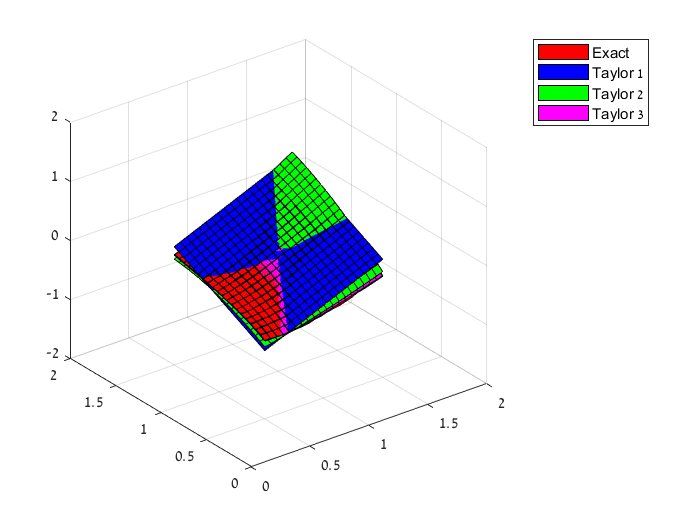

f = matlabFunction(f);
f_0 = f(1,1);
Tylor_1 = subs(Tylor_1,{x_0 y_0},{1 1});
Tylor_2 = subs(Tylor_2,{x_0 y_0},{1 1});
Tylor_3 = subs(Tylor_3,{x_0 y_0},{1 1});

Tylor_func_1 =  matlabFunction(f_0 + Tylor_1);
Tylor_func_2 =  matlabFunction(f_0 + Tylor_1 + Tylor_2);
Tylor_func_3 =  matlabFunction(f_0 + Tylor_1 + Tylor_2 + Tylor_3);


x = linspace(0.5,1.5,20);
y = linspace(0.5,1.5,20);
[X,Y] = meshgrid(x,y);

Z_1 = Tylor_func_1(X,Y);
Z_2 = Tylor_func_2(X,Y);
Z_3 = Tylor_func_3(X,Y);
Z_4 = f(X,Y);

figure
surf(X,Y,Z_4,'FaceColor','r','AlignVertexCenters','on')
hold on
surf(X,Y,Z_1,'FaceColor','b')
surf(X,Y,Z_2,'FaceColor','g')
surf(X,Y,Z_3,'FaceColor','m')
xlim ([0 2])
ylim ([0 2])
zlim ([-2 2])
legend('Exact','Taylor 1','Taylor 2','Taylor 3')